# Homework 1 

**Date: **1/26/2023 

**Name: **Georgios-Ierotheos Orfanidis

#### Table of contents:

- After you have indicated the desired image type, read an image from a drop-down menu into a workspace variable.

- Display the image by clicking the "Show Image" button.

- Apply an available image processing filter/effect to the loaded image.

- Display the processed by clicking the "Show Image" button.

-  Save the resulting image by specifying the file name and the file type.

#### Task 1: 

Read an image into a workspace variable.

a. Select type of image to load: 

image_type = "*.jpg";

cd('C:\Program Files\MATLAB\R2022a\toolbox\images\imdata');
image_list = dir(image_type);
image_list = string({image_list.name});

b. Load one of the available images of that type: 

I = imread(image_list(24));

#### **Task 2:**

Display the image by clicking the "Show Image" button.

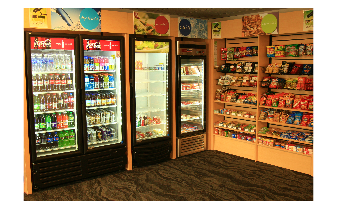

imshow(I);

#### Task 3: 

Apply an image processing filter/effect of your choice to the loaded image. 

a. Select one available filter: 

filtered_image = "increased_contrast_blurred";

b. Define filters:

increased_contrast = imadjust(I,[.3 .3 0; .5 .7 1],[]);
gray_scale = im2gray(I);
kernel = ones(20) / 20^2;
blurred = imfilter(I, kernel, 'conv');
increased_contrast_blurred = imfilter(increased_contrast, kernel, 'conv');

#### Task 4:

Display the result by clicking the "Show Image" button. 

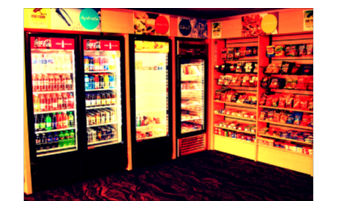

if filtered_image == "gray_scale"
    imshow(gray_scale);
    final_image = gray_scale;
elseif filtered_image == "increased_contrast"
    imshow(increased_contrast);
    final_image = increased_contrast;
elseif filtered_image == "increased_contrast_blurred"
    imshow(increased_contrast_blurred);
    final_image = increased_contrast_blurred;
else 
    imshow(blurred);
    final_image = blurred;
end

#### Task 5: 

Save the resulting image.

a. Select the type format to save the image: 

save_image_type = ".png";

b. Select the file name for your image (you can also specify the path): 

save_image_name = "test";

c. Save the image: 

cd('C:\Users\orfan\Documents\FAU\spring_2023\digital_image_processing\hw_1');
save_image_name = save_image_name + save_image_type;
imwrite(final_image, save_image_name);